# BIV Whirlpool-Galaxie Processing

Setup

dark_frame_file = "darkframe.tiff"

dark_frame_file = "darkframe.tiff"

background_file = "background_fit.tiff"

background_file = "background_fit.tiff"

raw_files = dir("raw/*.tiff")

raw_files = 108×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum



addpath('code');

Load darkframe and background

background = im2double(imread(background_file));

dark_frame = im2double(imread(dark_frame_file));
dark_frame = crop_to_match(dark_frame,background);

Load raw images and subtract darkframe and background


raw_images = {};
for k = 1:numel(raw_files)
    img = im2double(imread(fullfile("raw/", raw_files(k).name)));
    img = crop_to_match(img,background); % Crop images since background is slightly smaller
    img_calibrated = img - dark_frame;
    if false % remove background
        img_calibrated = img_calibrated - background;
    end

    img_calibrated(img < 0) = 0; % Clip negatives

    raw_images{end+1} = img_calibrated;
end

Reference image

reference = raw_images{1}

reference =     0.0181    0.0126    0.0116    0.0152    0.0103    0.0216    0.0143    0.0161    0.0181    0.0163    0.0112    0.0131    0.0143    0.0137    0.0218    0.0076    0.0186    0.0163    0.0215    0.0186    0.0148    0.0241    0.0199    0.0121    0.0079    0.0196    0.0092    0.0163    0.0111    0.0177    0.0113    0.0060    0.0115    0.0177    0.0120    0.0144    0.0217    0.0132    0.0111    0.0163    0.0061    0.0332    0.0121    0.0174    0.0207    0.0098    0.0091    0.0149    0.0160    0.0130
    0.0076    0.0057    0.0126    0.0060    0.0199    0.0081    0.0188    0.0126    0.0135    0.0033    0.0117    0.0181    0.0146    0.0095    0.0104    0.0047    0.0087    0.0083    0.0079    0.0126    0.0131    0.0166    0.0195    0.0135    0.0037    0.0108    0.0163    0.0074    0.0100    0.0088    0.0193    0.0036    0.0242    0.0222    0.0080    0.0092    0.0136    0.0075    0.0155    0.0059    0.0114    0.0103    0.0140    0.0121    0.0218    0.0088    0.0187    0.0070    0.0

Align images to reference

aligned_images = cell(size(raw_images));
aligned_images{1} = reference;

n = numel(raw_images);
h = waitbar(0, 'Aligning images...');

for k = 2:n
    moving_image = raw_images{k};
    
    % Detect stars
    points_fixed  = get_star_tracking_points(reference);
    points_moving = get_star_tracking_points(moving_image);

    [points_fixed, points_moving] = match_points(points_fixed, points_moving);
    
    % Find transform
    tform = estimateGeometricTransform2D(points_fixed, points_moving, 'similarity');
    
    % Warp image
    output_view = imref2d(size(reference));
    aligned = imwarp(moving_image, tform, "OutputView", output_view);
    
    aligned_images{k} = aligned;

    waitbar(k/n, h, sprintf('Aligned %d of %d images', k, n));
end

close(h);

Stack images

stack_sum = zeros(size(reference));
for k = 1:numel(aligned_images)
    stack_sum = stack_sum + aligned_images{k};
end
stack_mean = stack_sum/n;

Background Correction

Save

save_image(stack_mean, "output.tif");

Crop

margin_from_edge = 20

margin_from_edge = 20

cropped = circular_crop(stack_mean, margin_from_edge);

Display

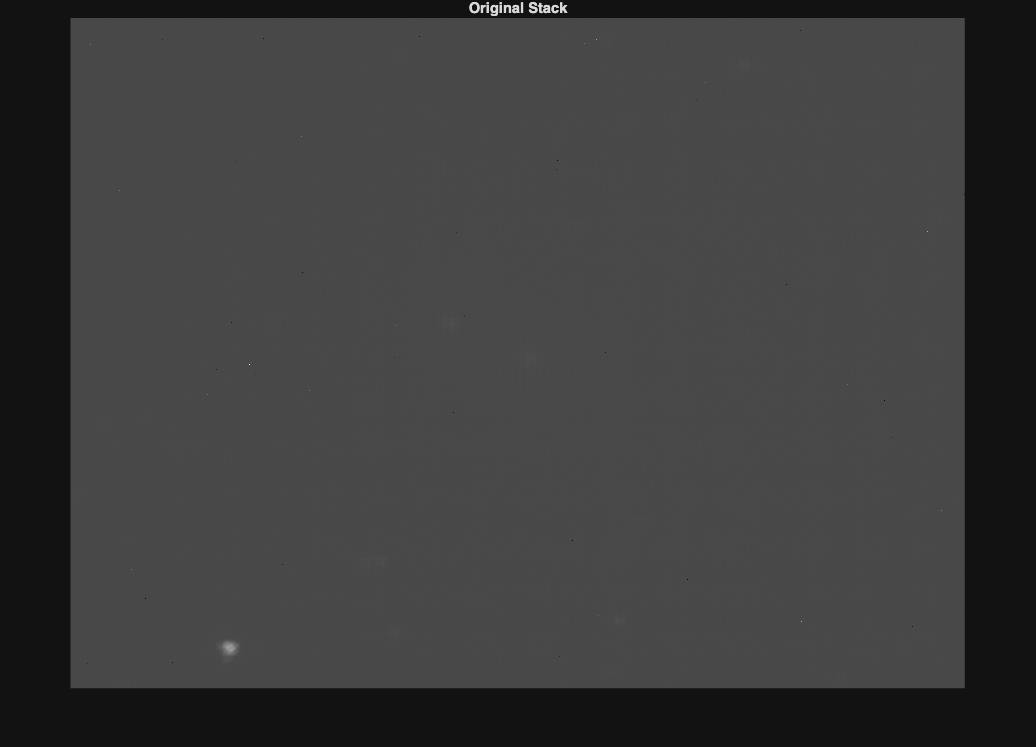

figure; imshow(stack_mean, []); title('Original Stack');

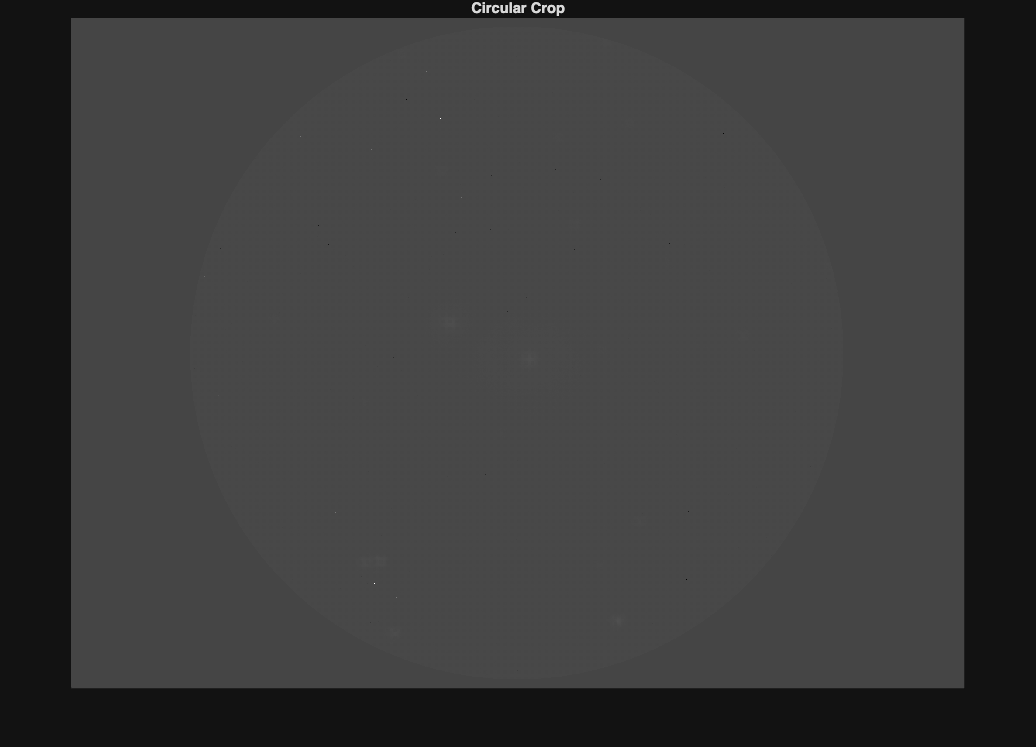

figure; imshow(cropped, []); title('Circular Crop');

PostProcess

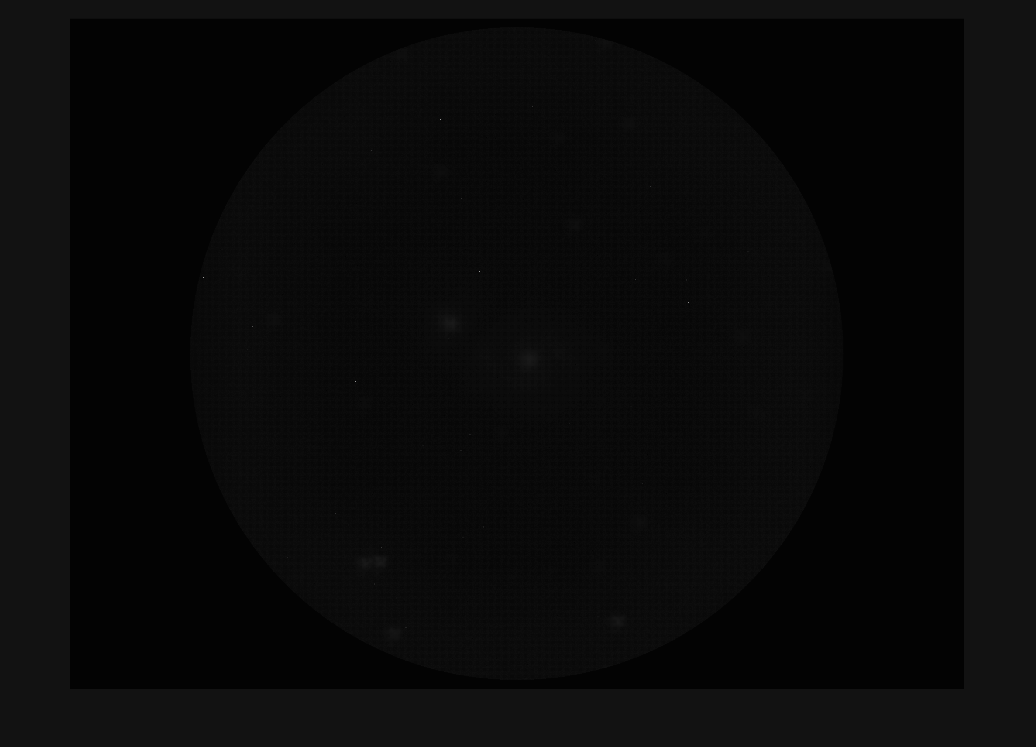

% img_clean is your background-subtracted image
noise_thresh = 0.00001;   % adjust to suppress background noise
img_thresh = cropped;
img_thresh(img_thresh < noise_thresh) = 0;

img_stretch = adapthisteq(img_thresh, ClipLimit=0.01);  % map 5–95% to full range

img_smooth = imgaussfilt(img_stretch, 0.5);  % sigma = 0.5-1 pixel


imshow(img_smooth)